clear; clc; close all;
syms x(t) zeta omega_n x_0 x_dot_0

v = diff(x, t);
a = diff(x, t, 2);
eq = a + 2*zeta*omega_n*v + omega_n^2*x == 0

$$eq(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+2\,\zeta \,\omega_{n}\,\frac{\partial }{\partial t}x\left(t\right)+x\left(t\right)\,{\omega_{n}}^{2}=0$$

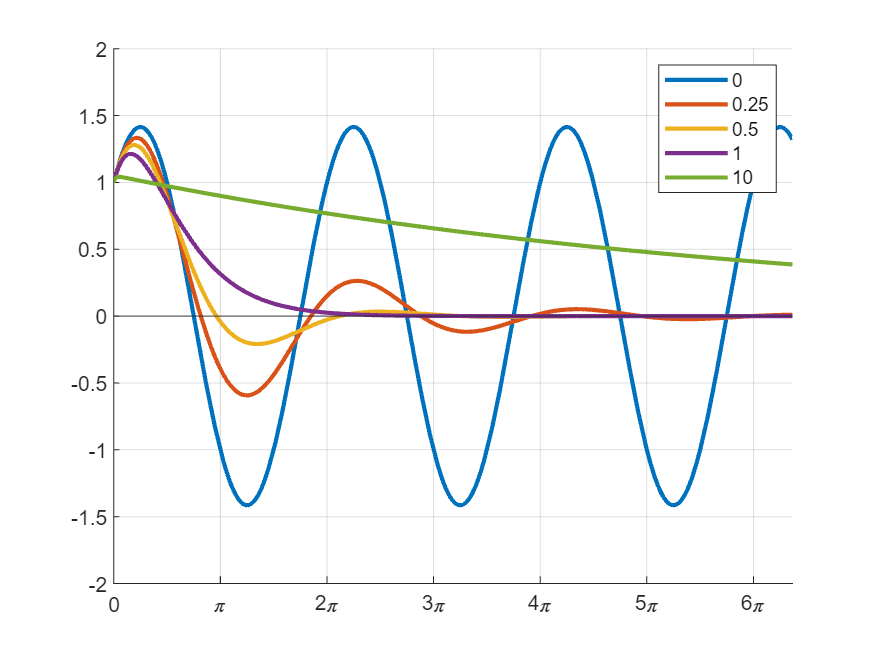

zeta_array = [0, 0.25, 0.5, 1, 10];

figure; hold on;
for i=1:length(zeta_array)
    x_sol = dsolve(subs(eq, zeta, zeta_array(i)), x(0)==x_0, v(0)==x_dot_0);
    x_sol = simplify(expand(rewrite(x_sol, "sincos")));
    x_sol = subs(x_sol, [x_0, x_dot_0, omega_n], [1, 1, 1]);

    fplot(x_sol, [0, 20], LineWidth=1.5); hold on;
    ylim([-2 2])
    
end
grid on;
xticks([0, pi, 2*pi, 3*pi, 4*pi, 5*pi, 6*pi]);
xticklabels({'0', '\pi','2\pi','3\pi','4\pi','5\pi','6\pi'})
yline(0);
legend("0", "0.25", "0.5", "1", "10");